# **Reto 1** 

# Profundización 1 Electromedicina

Hamilton Hernández - 219160360

Andres Peña - 216160223

Santiago Quiroz - 218160293

# **Restauración de señales de ECG** 

clear variables
close all
clc
warning('off','all');

## Señal desde Base de Datos

Se carga la señal ECG de la base de datos propuesta

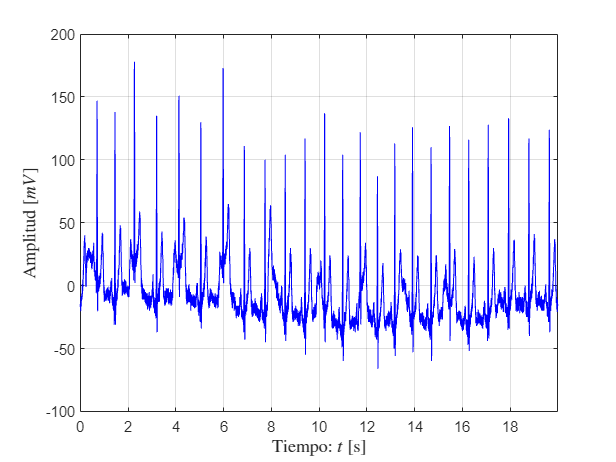

ECG_load = fopen("ecg\Person_01\rec_1.dat","r");
ECG_read = fread(ECG_load,inf,'*int16');
ECG_r = double(ECG_read(1:2:end));
ECG_f = double(ECG_read(2:2:end));
fs = 500;
ts = 1/fs;
L = length(ECG_r);
t = (0:L-1)*ts;

figure;
set(gcf,'color','w');
plot(t,ECG_r,'b');
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

## Fourier

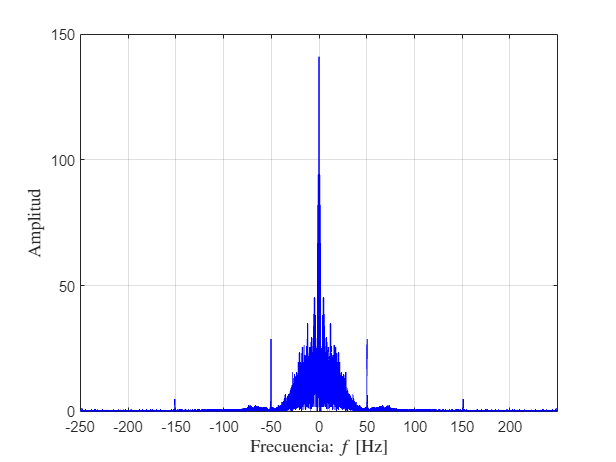


[f,ECG_fourier_r] = fourier(ECG_r,fs); 

%-----------------Analisis de fourier--------------
figure;
set(gcf,'color','w');
plot(f,ECG_fourier_r,'b','LineWidth',1);
grid on;
xlim([f(1),f(end)]);
xlabel('Frecuencia: $f$ [Hz]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud','FontSize',12,'Interpreter','latex');

Tras realizar el analisis de Fourier se observan componentes de ruido en los 50 Hz, también se pude ver la componente DC y algunas componentes de alta frecuencia que deberán ser filtradas posteriormente.

## Filtro Notch

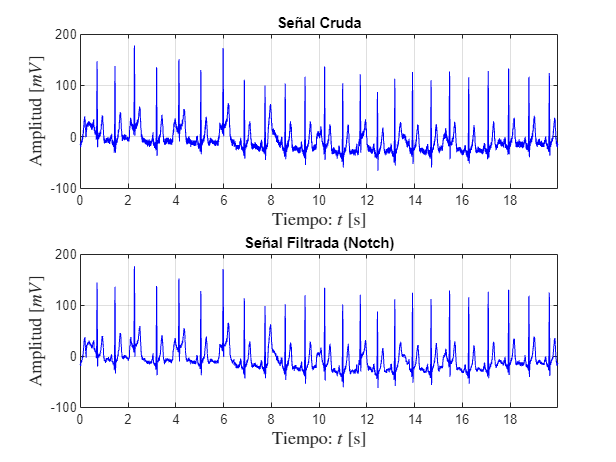

ECG_notch= fbutt(ECG_r,[48,52],fs,'stop',2);
[~,ECG_notch_fourier] = fourier(ECG_notch,fs);
%-----------------Grafico aplicando filtro notch--------------
%Original
figure;
set(gcf,'color','w');
subplot(2,1,1)
plot(t,ECG_r,'b');
title("Señal Cruda")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

%Filtrada
subplot(2,1,2)
plot(t,ECG_notch,'b');
title("Señal Filtrada (Notch)")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

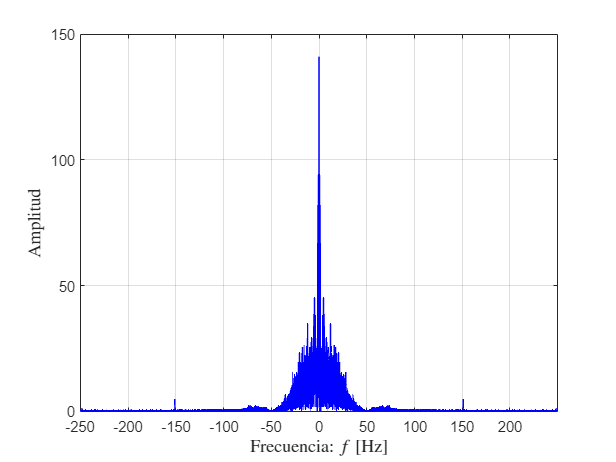


%-----------------Analisis de fourier--------------
figure;
set(gcf,'color','w');
plot(f,ECG_notch_fourier,'b','LineWidth',1);
grid on;
xlim([f(1),f(end)]);
xlabel('Frecuencia: $f$ [Hz]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud','FontSize',12,'Interpreter','latex');

## Filtro Pasa Bajas

Ahora se aplica un filtro pasa bajas con frecuencia de corte en 100Hz para eliminar las altas frecuencias.

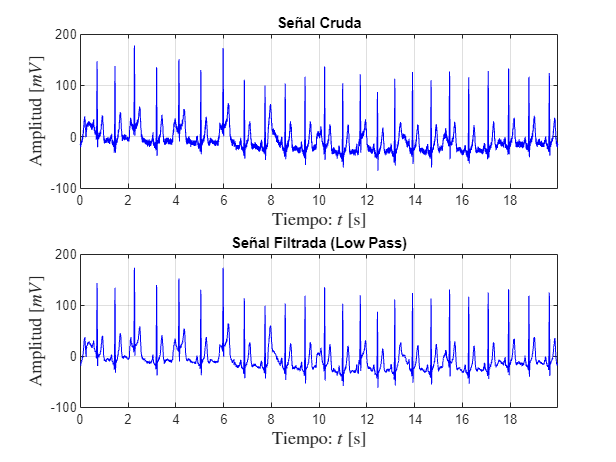

ECG_lowpass=fbutt(ECG_notch,100,fs,"low",4);
[~,ECG_lowpass_fourier]=fourier(ECG_lowpass,fs);

%-----------------Grafico aplicando filtro notch--------------
%Original
figure;
set(gcf,'color','w');
subplot(2,1,1)
plot(t,ECG_r,'b');
title("Señal Cruda")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

%Filtrada
subplot(2,1,2)
plot(t,ECG_lowpass,'b');
title("Señal Filtrada (Low Pass)")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

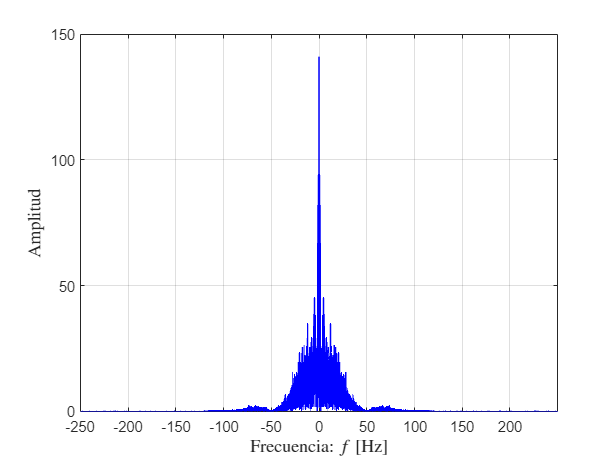


%-----------------Analisis de fourier--------------
figure;
set(gcf,'color','w');
plot(f,ECG_lowpass_fourier,'b','LineWidth',1);
grid on;
xlim([f(1),f(end)]);
xlabel('Frecuencia: $f$ [Hz]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud','FontSize',12,'Interpreter','latex');

## Filtro Pasa Altas

Ahora se aplica un filtro pasa altas con frecuencia de corte en 0.1Hz para eliminar componente DC.

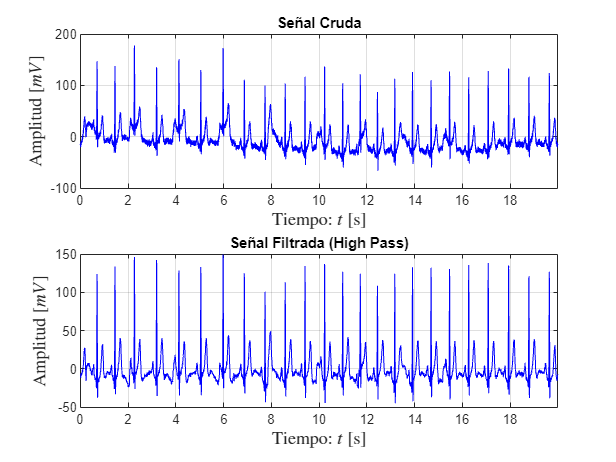

ECG_highpass=fbutt(ECG_lowpass,1,fs,'high',4);
[~,ECG_highpass_fourier]=fourier(ECG_highpass,fs);

%-----------------Grafico aplicando filtro notch--------------
%Original
figure;
set(gcf,'color','w');
subplot(2,1,1)
plot(t,ECG_r,'b');
title("Señal Cruda")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

%Filtrada
subplot(2,1,2)
plot(t,ECG_highpass,'b');
title("Señal Filtrada (High Pass)")
grid on;
xlim([t(1),t(end)]);
xlabel('Tiempo: $t$ [s]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud $[mV]$','FontSize',12,'Interpreter','latex');

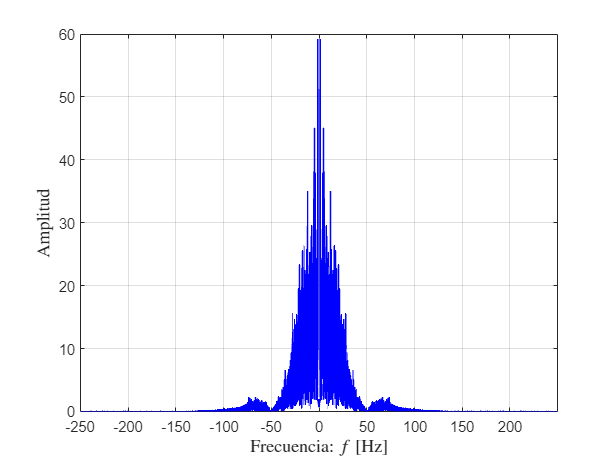


%-----------------Analisis de fourier--------------
figure;
set(gcf,'color','w');
plot(f,ECG_highpass_fourier,'b','LineWidth',1);
grid on;
xlim([f(1),f(end)]);
xlabel('Frecuencia: $f$ [Hz]','FontSize',12,'Interpreter','latex');
ylabel('Amplitud','FontSize',12,'Interpreter','latex');